% clear mypi;
% clear;
% mypi=raspi("192.168.43.6","Kollis","646djohr");

%%% 31250 sampler = 1 sek
system(mypi,'lab4/./radar_sampler 125000 /home/Kollis/lab4/SAMPLE.bin','sudo');
getFile(mypi,'/home/Kollis/lab4/SAMPLE.bin','C:\GitHub\TTT4280-Sensorer\Lab4');
deleteFile(mypi, '/home/Kollis/lab4/SAMPLE.bin');

channels=2;
nBits=12;
VDD=3.3;
f_radar=24.13*10^9;
c=3*10^8;
j=sqrt(-1);

fid=fopen("SAMPLE.bin","rb");
nomPeriod=fread(fid,1,"double");
nomPeriod = nomPeriod * 1e-6;
data=fread(fid,"uint16");
nSamples=numel(data)/channels; 
fs=1/nomPeriod;
dataMatrix = reshape(data,channels,nSamples);
fclose(fid);

n=0:nSamples-1;
t=n*nomPeriod;

h=transpose(hann(nSamples));
I=(dataMatrix(1,:))*VDD/(2.^nBits); 
Q=(dataMatrix(2,:))*VDD/(2.^nBits); 
I=I-mean(I); I(1)=0;
Q=Q-mean(Q); Q(1)=0;

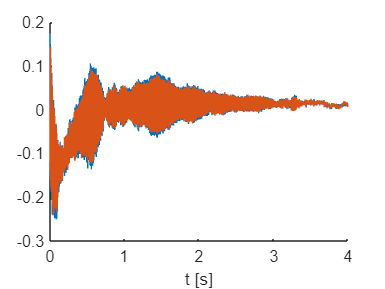

figure;
hold on;
plot(t,I);
plot(t,Q);
hold off;
xlabel("t [s]")

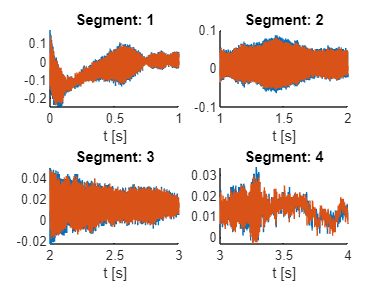

nSplit = 4; 
I_split = split_signal(I, nSplit);
Q_split = split_signal(Q, nSplit);
t_split = split_signal(t, nSplit);

nRows = ceil(sqrt(nSplit));
nCols = ceil(nSplit / nRows);

figure;
for i = 1:nSplit
    subplot(nRows, nCols, i);
    hold on;
    plot(t_split{i},I_split{i});
    plot(t_split{i},Q_split{i});
    hold off;
    xlabel("t [s]")
    title("Segment: " + i);
end

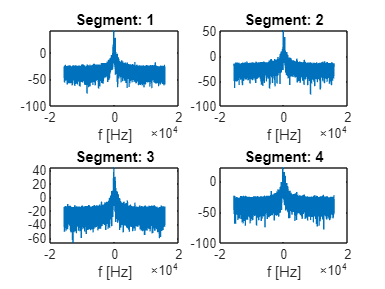

x=h.*(I+j*Q);
x=highpass(x,10,fs);
N_fft=pow2(ceil(log2(nSamples/nSplit)));
x_split=split_signal(x,nSplit);

X_segmented = zeros(nSplit, N_fft); 
for i = 1:nSplit
    X_segmented(i, :) = abs(fftshift(fft(x_split{i}, N_fft)));
end

S_segmented=20*log10(X_segmented);
f=1/(N_fft*nomPeriod)*(-N_fft/2:N_fft/2-1);

figure;
for i = 1:nSplit
    subplot(nRows, nCols, i);
    plot(f,S_segmented(i,:));
    xlabel("f [Hz]")
    title("Segment: " + i);
end

v_rad = zeros(1, nSplit);
f_d = zeros(1, nSplit);
snr_I = zeros(1, nSplit);
snr_Q = zeros(1, nSplit);

for i = 1:nSplit
    [max_amp, max_idx] = max(X_segmented(i, :));
    f_d(i) = f(max_idx);
    
    if abs(f_d(i)) < 10
        v_rad(i) = 0;
    else
        v_rad(i) = c * f_d(i) / (2 * f_radar);
    end
    
    snr_I(i) = snr(I_split{i});
    snr_Q(i) = snr(Q_split{i});
end
v_mean=mean(v_rad);
v_std=sqrt(var(v_rad));

disp(['Gjennomsnitthastighet: ', num2str(v_mean),' m/s']);

Gjennomsnitthastighet: -1.6466 m/s


disp(['Standardavvik hastighet: ', num2str(v_std),' m/s']);

Standardavvik hastighet: 0.57929 m/s


disp('Resultater for hvert segment:');

Resultater for hvert segment:


disp('-----------------------------');

-----------------------------


for i = 1:nSplit
    disp(['Segment ', num2str(i)]);
    disp(['Radiell hastighet: ', num2str(v_rad(i)), ' m/s']);
    disp(['Dopplerskift: ', num2str(f_d(i)), ' Hz']);
    disp(['SNR I: ', num2str(snr_I(i))]);
    disp(['SNR Q: ', num2str(snr_Q(i))]);
    disp('---------------------');
end

Segment 1


Radiell hastighet: -1.4643 m/s


Dopplerskift: -235.5576 Hz


SNR I: 17.1752


SNR Q: 17.2394


---------------------


Segment 2


Radiell hastighet: -1.3991 m/s


Dopplerskift: -225.0671 Hz


SNR I: 19.2424


SNR Q: 19.3516


---------------------


Segment 3


Radiell hastighet: -1.2212 m/s


Dopplerskift: -196.4569 Hz


SNR I: 0.9461


SNR Q: 0.94201


---------------------


Segment 4


Radiell hastighet: -2.5018 m/s


Dopplerskift: -402.4506 Hz


SNR I: -8.8298


SNR Q: -7.6895


---------------------


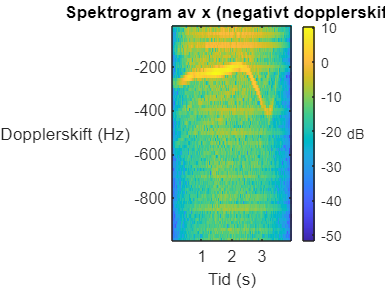

% Beregn gjennomsnittlig dopplerskift
f_d_mean = mean(f_d);

% Bestem retningen basert på gjennomsnittlig dopplerskift
if f_d_mean < 0
    doppler_direction = 'negativ';
else
    doppler_direction = 'positiv';
end

window_length = 2048;
overlap = window_length / 2;
% Beregn spektrogrammet
[s, f_spec, t_spec] = spectrogram(x, window_length, overlap, [], fs);

freq_range = [10, 2.5*max(abs(f_d))];
freq_idx = f_spec >= freq_range(1) & f_spec <= freq_range(2);
f_spec = f_spec(freq_idx);
s = s(freq_idx, :);
v_spec = abs(f_spec) * c / (2 * f_radar);

% Plot spektrogrammet med dopplerskift på y-aksen
figure;
if strcmp(doppler_direction, 'negativ')
    imagesc(t_spec, -f_spec, 10*log10(abs(s))); % Inverterer y-aksen for negativ dopplerskift
else
    imagesc(t_spec, f_spec, 10*log10(abs(s))); % Positiv dopplerskift
end
axis xy;
xlabel('Tid (s)');
ylabel('Dopplerskift (Hz)');
title(['Spektrogram av x (', doppler_direction, 't dopplerskift)']);
cb = colorbar;
ylabel(cb, 'dB');
set(get(cb,'ylabel'),'rotation',0);
set(get(gca,'ylabel'),'rotation',0);

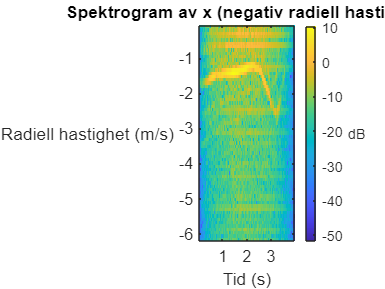


% Plot spektrogrammet med radiell hastighet på y-aksen (positiv)
figure;
if strcmp(doppler_direction, 'negativ')
    imagesc(t_spec, -v_spec, 10*log10(abs(s))); % Inverterer y-aksen for negativ dopplerskift
else
    imagesc(t_spec, v_spec, 10*log10(abs(s))); % Positiv dopplerskift
end
axis xy;
xlabel('Tid (s)');
ylabel('Radiell hastighet (m/s)');
title(['Spektrogram av x (', doppler_direction, ' radiell hastighet)']);
cb = colorbar;
ylabel(cb, 'dB');
set(get(cb,'ylabel'),'rotation',0);
set(get(gca,'ylabel'),'rotation',0);